clear;clc;

% load parameters
par = importdata('par_scg.txt');
par = par.data;

% initial values
y0 = zeros(4, 1);
y0(1) = 1;
y0(4) = 0;

tmax = 100;
tspan = 0:0.1:tmax;

[~, y] = ode45(@ODE_SCG, tspan, y0, [], par);

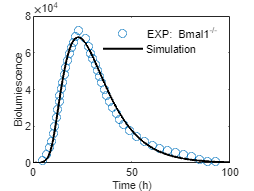

biolu_data_ko = importdata('biolu_data_ko.txt');

figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
scatter(biolu_data_ko(:, 1), biolu_data_ko(:, 2));
plot(tspan, y(:, 4), 'LineWidth', 1.5, 'Color', 'k');
xticks([0 50 100]);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',8, 'FontName', 'Arial');
legend('EXP: Bmal1^{-/-}', 'Simulation', 'Box', 'off','Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);

% set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);